clc,clear
% matlab中，不存在的边设置成0
% 9个顶点，初始化定义9x9的全零矩阵作为邻接矩阵
a = zeros(9);

% 注意，最小生成树是针对无向图的，每条边权重只需要设一次。1到2和2到1是同一条边
% 因此，可仅使用邻接矩阵的上三角矩阵来构造图G
a(1,[2:9])=[2 1 3 4 4 2 5 4];       % 顶点1到其他顶点的边的权重
a(2,[3 9])=[4 1];   % 顶点2到顶点3、顶点9的边的权重
a(3,4)=1;       % 同上。因为写过1到3，和2到3的边的权重，无需重复设
a(4,5)=1;       
a(5,6)=5;
a(6,7)=2; 
a(7,8)=3; 
a(8,9)=5;

% cellstr和graph在最短路径课程中讲过
s=cellstr(strcat('v',int2str([1:9]')));
G=graph(a,s,'upper');  % 仅使用 A 的上三角矩阵来构造图G。
p=plot(G,'EdgeLabel',G.Edges.Weight);   % 绘制出图G

% minspantree函数求解最小生成树
% T=minspantree(G)是默认使用Prim算法
T=minspantree(G,'Method','sparse');      % 可指定使用Kruskal算法

L = sum(T.Edges.Weight)     % 对最小生成树的边的权重求和

L = 13

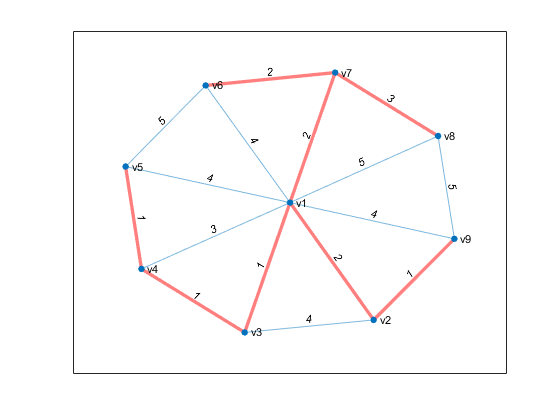

highlight(p,T,"EdgeColor","red",'LineWidth',2.5)

%本文件出自b站/公众号：数学建模BOOM
% 关注公众号：数学建模BOOM，回复"购买"
% 获取全套视频课程+配套PPT课件+代码文件+完善售后服务+后续课程更新
% 版权所有，侵权必究。本文件仅供购买者学习使用，不得随意传播，否则为侵权行为